# 第5章 数字滤波器结构

## 5.2 无限长单位脉冲响应数字滤波器结构

### 5.2.1 直接型

#### Ch5_2_1

`采用直接型实现系统函数如下的`IIR`数字滤波器，并求单位脉冲响应`$h\left(n\right)$


$$H\left(z\right)=\frac{\sum_{r=0}^M b_r z^{-r} }{1-\sum_{k=1}^N a_k z^{-k} }=\frac{1-3z^{-1} +11z^{-2} +27z^{-3} +18z^{-4} }{16+12z^{-1} +2z^{-2} -4z^{-3} -2z^{-4} }$$


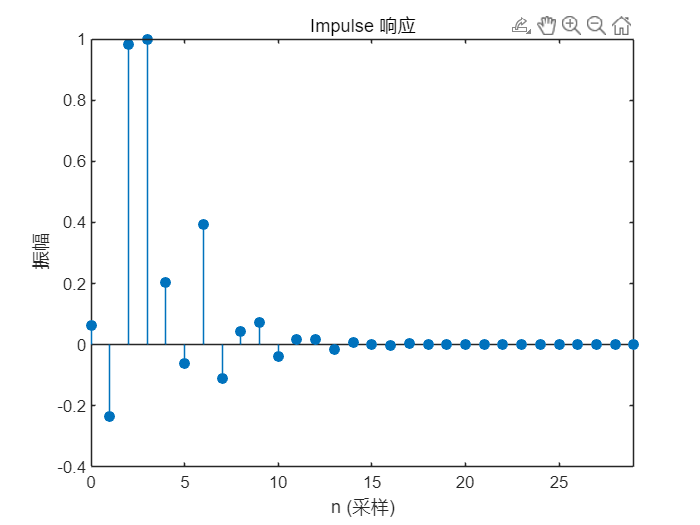

b = [1,-3,13,27,18];
a = [16,12,2,-4,-2];
impz(b,a,30);

z-1 延迟器

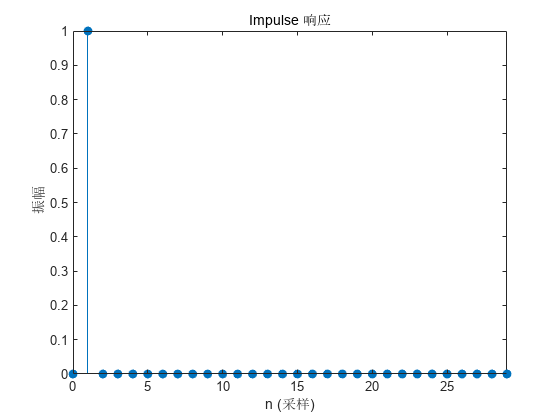

b = [0,1];
a = 1;
impz(b,a,30);

num = b;
den = a;
fvtool(num,den);

[h1,t] = impz(b,a,11);

% h = [0 1 0 0 0 0 0 0 0 0 0]';
h = h1;

x = [1 1 1 1 1 1 1 1 1 1 1]';
x_plus = [1 1 1 1 1 1 1 1 1 1 1 0 0 0 0 0 0 0 0 0 0]';
y = conv(x,h)

y =      0
     1
     1
     1
     1
     1
     1
     1
     1
     1


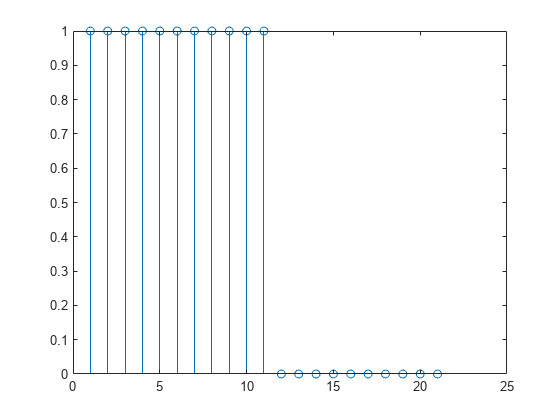

stem(x_plus);

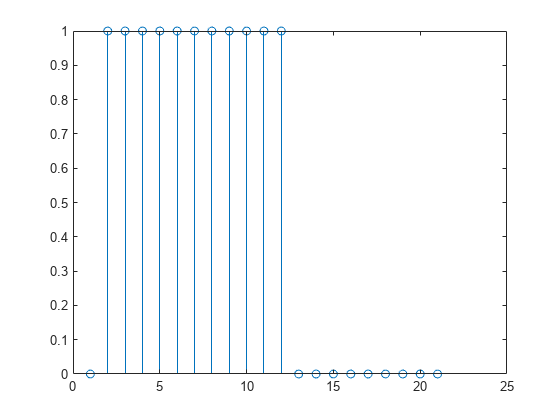

stem(y); 

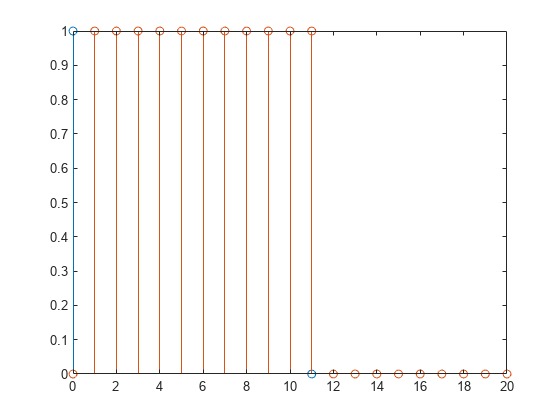

x1 = linspace(0,20,21)';
x2 = linspace(0,20,21)';
X = [x1, x2];
Y = [x_plus, y];

stem(X,Y)

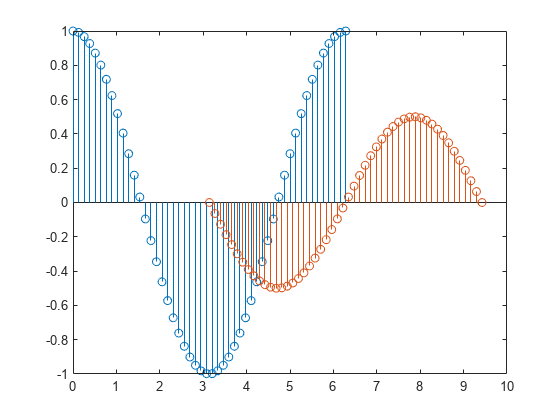


figure
x1 = linspace(0,2*pi,50)';
x2 = linspace(pi,3*pi,50)';
X = [x1, x2];
Y = [cos(x1), 0.5*sin(x2)];
stem(X,Y)